clear, clc;
data = load("polarPatternsIn.mat");
polarPatternsIn = data.polarPatternsIn;

% General params
fig_size = [0 0 1100 400];
linewidth = 1.5;

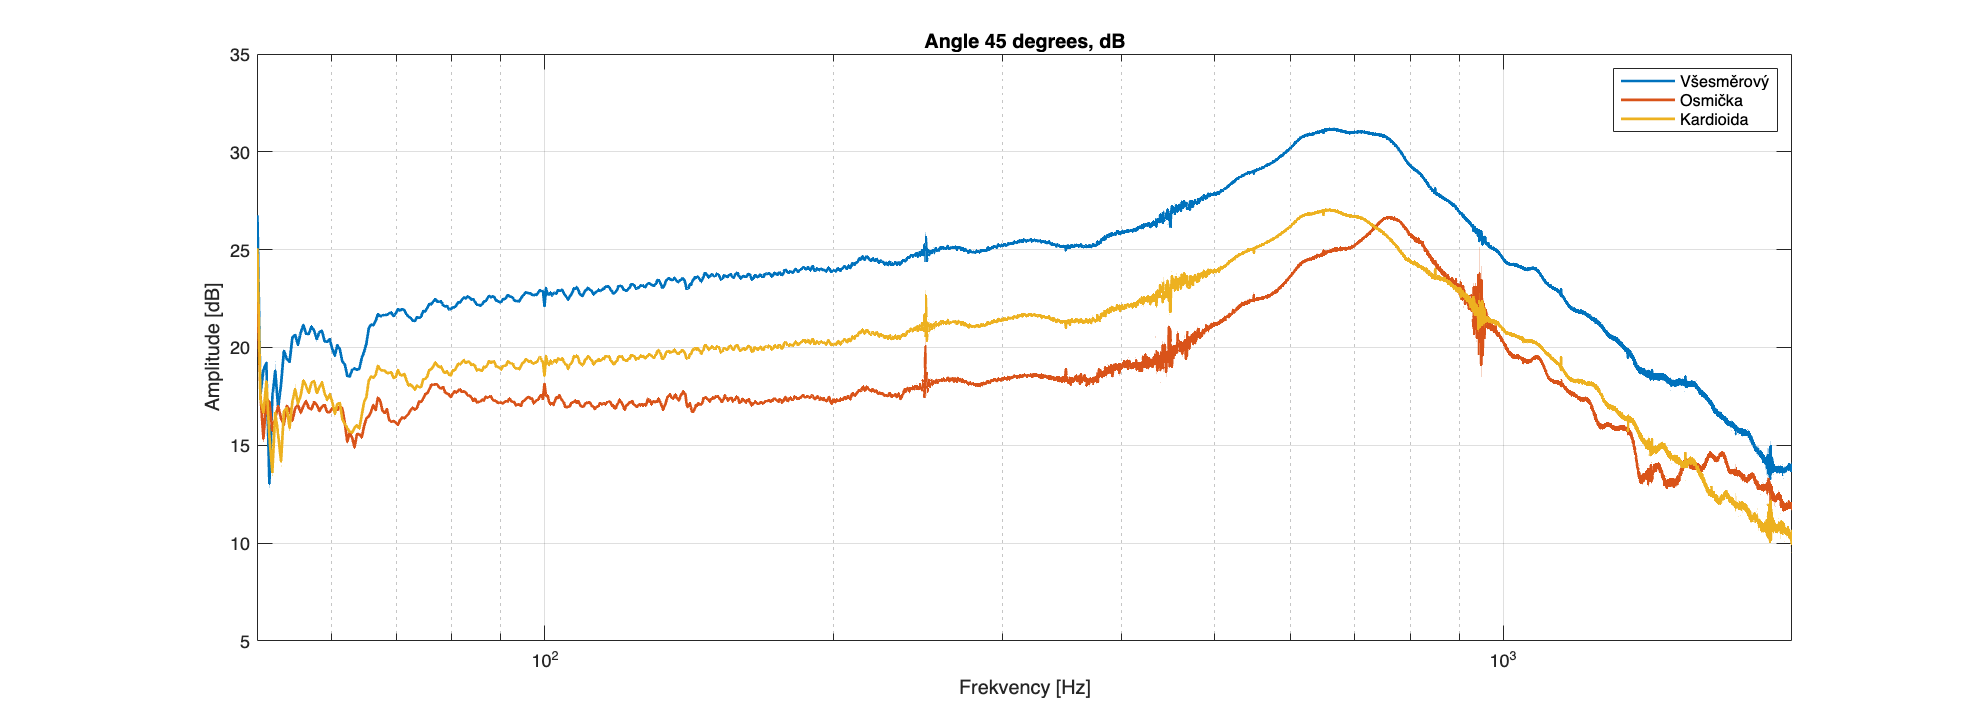

fs = 48000;            % DOSAĎ skutečnou frekvenci měření: ppSampleRate
poloha = 1;            % stejná poloha jako v aplikaci
kanaly = 1:size(polarPatternsIn, 2);

N = size(polarPatternsIn, 1);
f = (0:N-1).' * fs/N;  % frekvence jednotlivých FFT binů

% Dosaď stejný rozsah jako v aplikaci:
fmin = 50;  

fmax = 2000;
vyber = f >= fmin & f <= min(fmax, fs/2);

CH1norm = polarPatternsIn(:,1,:);%/Ratio1to3;
CH2norm = polarPatternsIn(:,2,:);%/Ratio2to4;
CH3norm = polarPatternsIn(:,3,:);%/Ratio3to4;
CH4norm = polarPatternsIn(:,4,:);

polarPatternsOut(:, 1, :) = (CH1norm + CH2norm + CH3norm + CH4norm) / 4; % Všesměrový
polarPatternsOut(:, 2, :) = (CH2norm - CH4norm) / 2; % Osmička
polarPatternsOut(:,3,:) = (polarPatternsOut(:, 1, :) + polarPatternsOut(:, 2, :)) / 2; % Kardioida?

ratio = polarPatternsOut(:, 1, :) ./ polarPatternsOut(:, 2, :);

figure('Position', fig_size);
semilogx(f(vyber), 10*log10(abs(polarPatternsOut(vyber, :, 22))), 'LineWidth', linewidth);
grid on;
xlabel('Frekvency [Hz]');
ylabel('Amplitude [dB]');
title('Angle 45 degrees, dB')
legend(compose(["Všesměrový", "Osmička", "Kardioida"]));

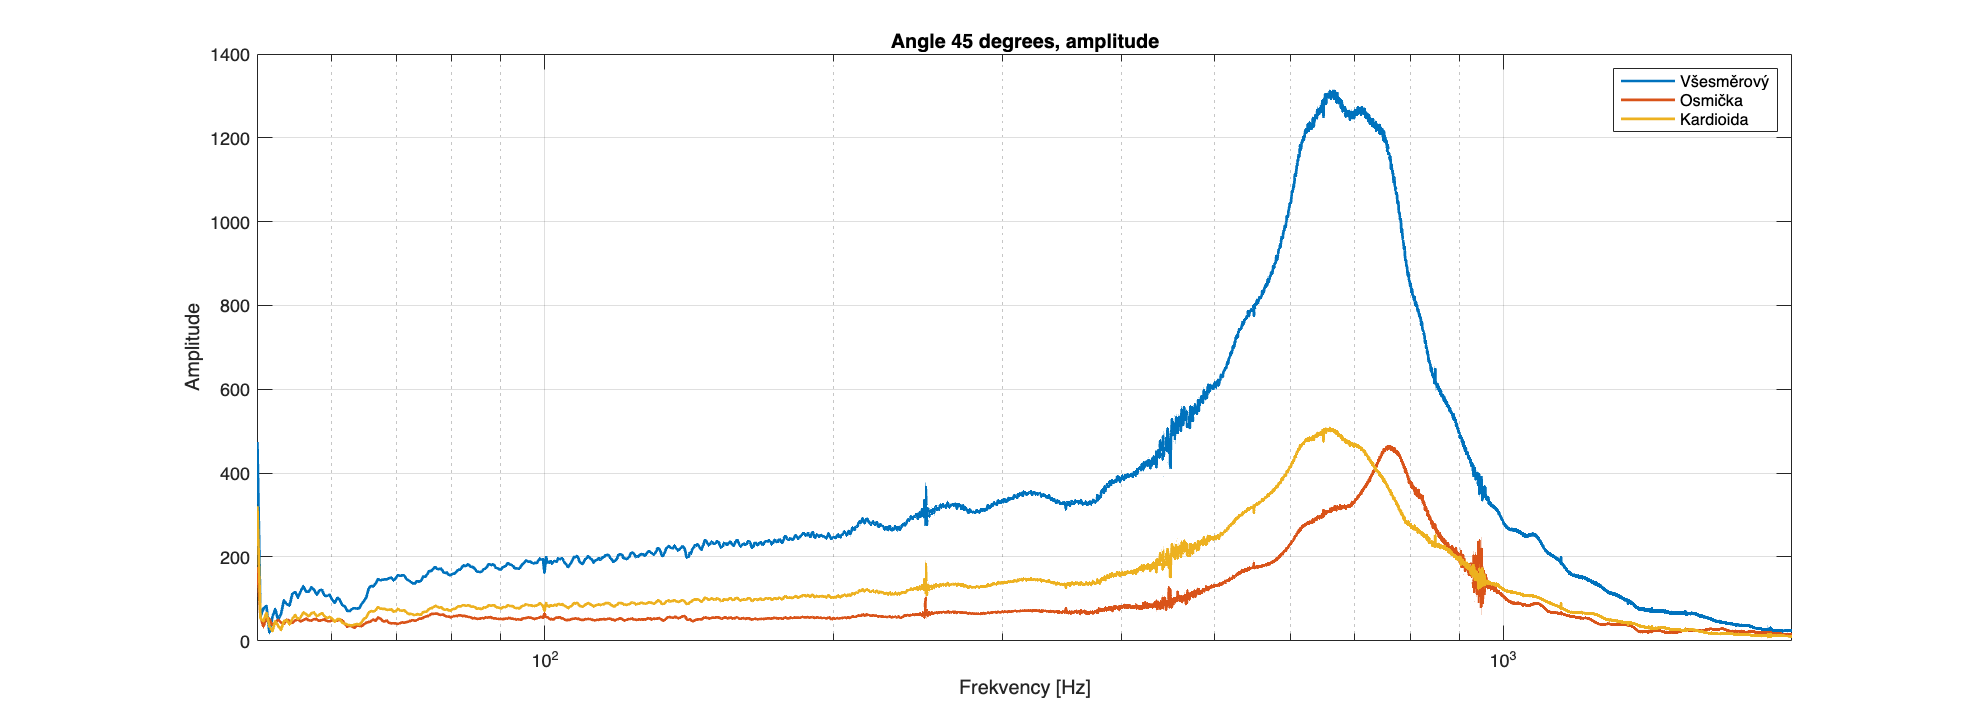


figure('Position', fig_size);
semilogx(f(vyber), abs(polarPatternsOut(vyber, :, 22)), 'LineWidth', linewidth);
grid on;
xlabel('Frekvency [Hz]');
ylabel('Amplitude');
title('Angle 45 degrees, amplitude')
legend(compose(["Všesměrový", "Osmička", "Kardioida"]));

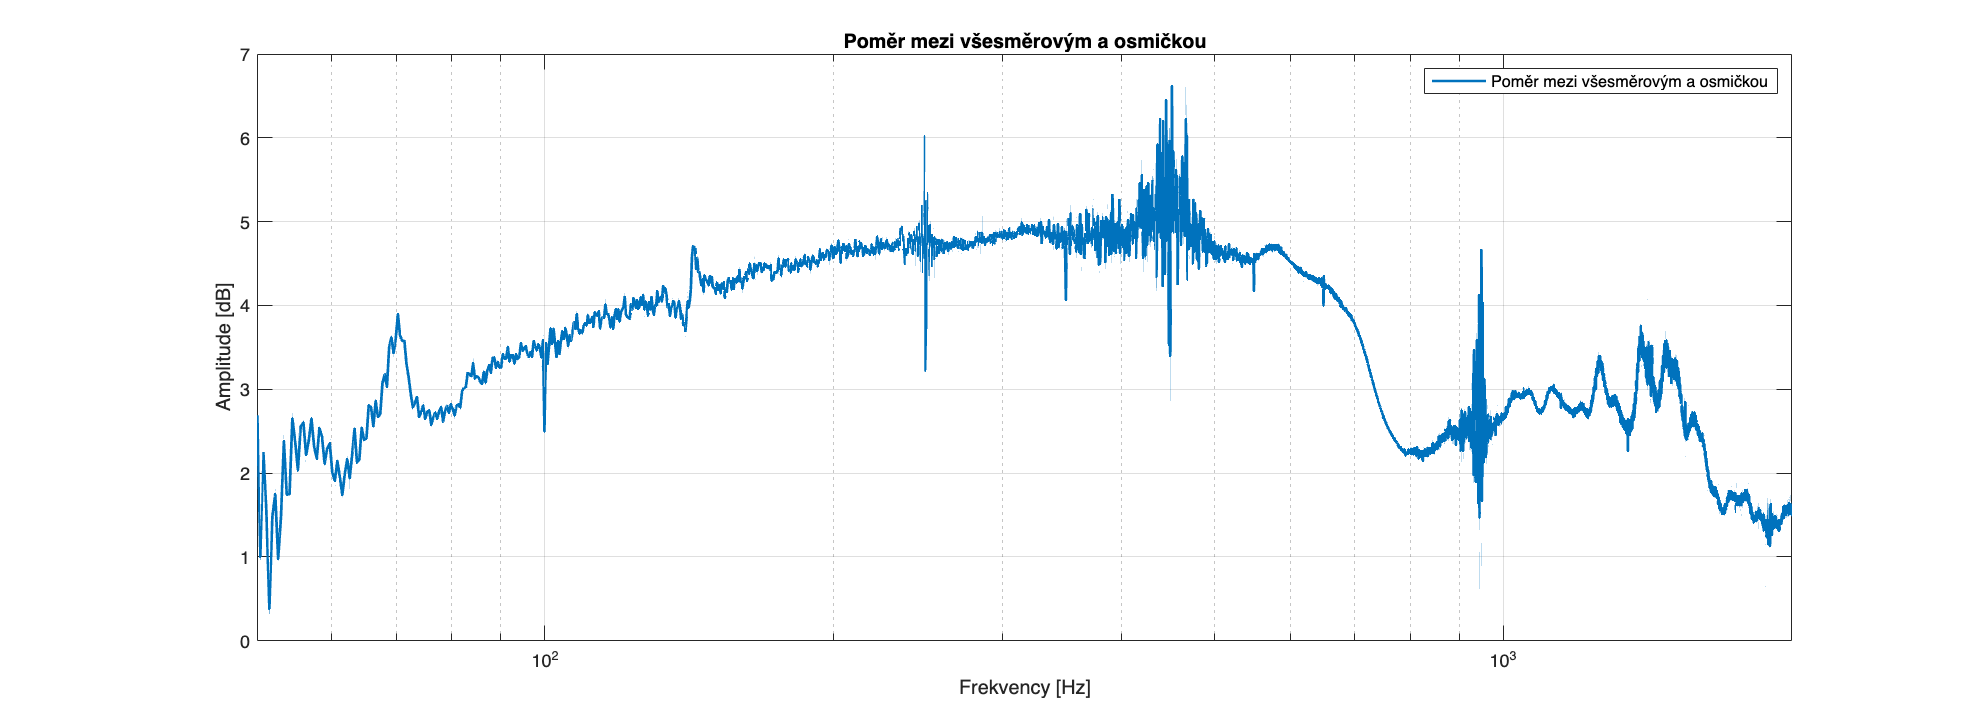


figure('Position', fig_size);
semilogx(f(vyber), abs(ratio(vyber, :, 22)), 'LineWidth', linewidth);
grid on;
xlabel('Frekvency [Hz]');
ylabel('Amplitude [dB]');
title("Poměr mezi všesměrovým a osmičkou")
legend(compose(["Poměr mezi všesměrovým a osmičkou"]));

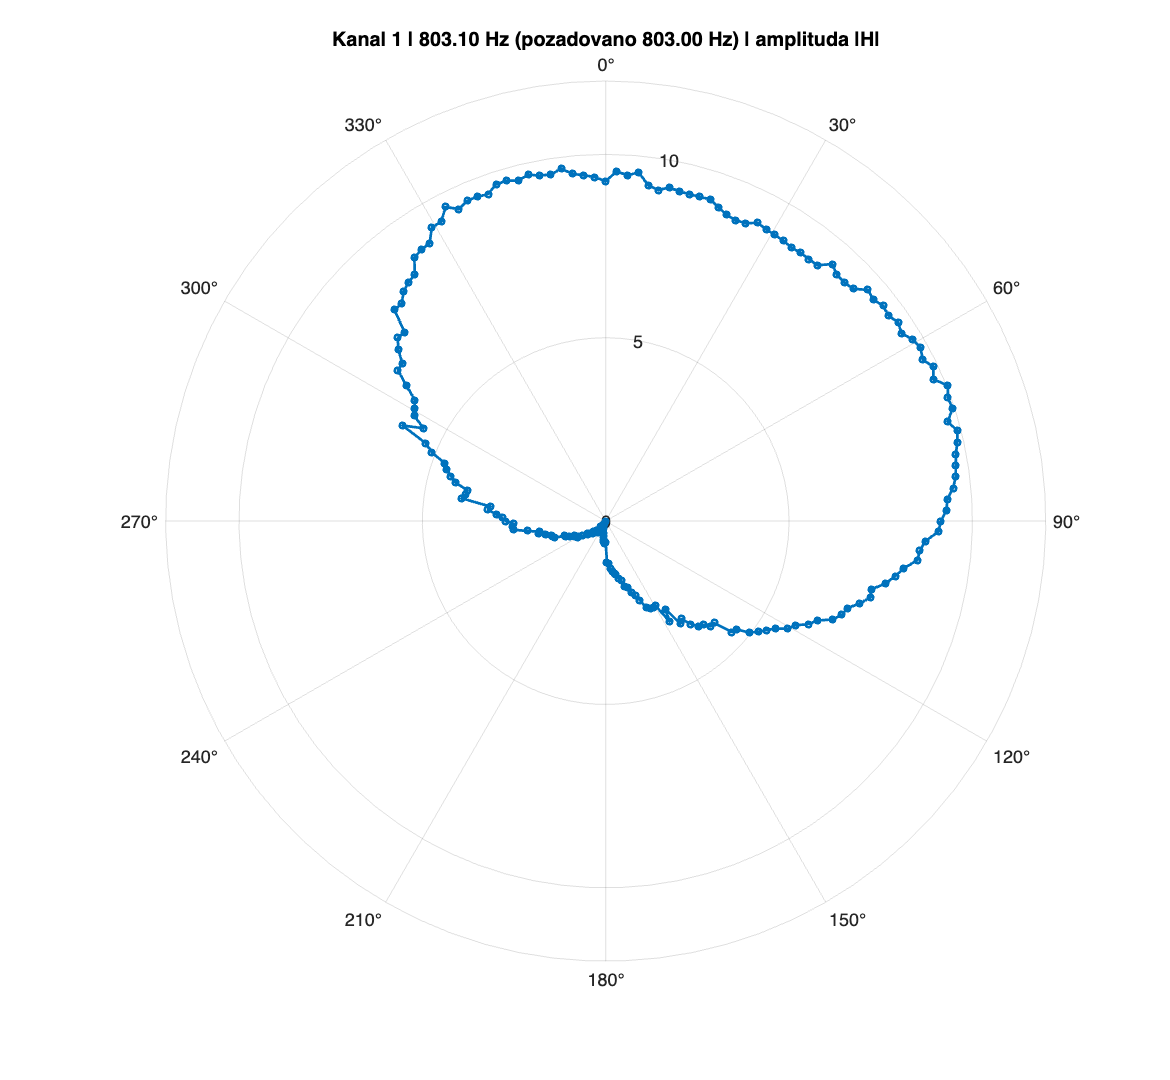

% Polarni charakteristika jednoho kanalu na zvolene frekvenci
polarChannel = 1;          % Index kanalu ve druhe dimenzi polarPatternsIn
polarFrequencyHz = 803;   % Pozadovana frekvence [Hz]
polarNormalize = false;    % true: normalizovat maximum na 1

% Spust nejprve bunku s nactenim dat a nastav fs podle mereni.
validateattributes(fs, {'numeric'}, {'scalar', 'real', 'finite', 'positive'});
validateattributes(polarChannel, {'numeric'}, ...
    {'scalar', 'integer', '>=', 1, '<=', size(polarPatternsIn, 2)});
validateattributes(polarFrequencyHz, {'numeric'}, ...
    {'scalar', 'real', 'finite', '>=', 0, '<=', fs/2});

polarN = size(polarPatternsIn, 1);
polarBin = min(round(polarFrequencyHz * polarN / fs), floor(polarN/2)) + 1;
polarActualFrequencyHz = (polarBin - 1) * fs / polarN;
polarAmplitude = reshape(abs(polarPatternsIn(polarBin, polarChannel, :)), [], 1);
%polarPSD = 10*log10(abs(polarAmplitude).^2)
polarAmplitude = 20*log10(polarAmplitude / max(polarAmplitude));

if polarNormalize
    polarPeak = max(polarAmplitude);
    if isfinite(polarPeak) && polarPeak > 0
        polarAmplitude = polarAmplitude / polarPeak;
    end
end

% Rovnomerne kroky cele otacky: 0, 360/M, ..., 360*(M-1)/M stupnu.
% Pokud mereni pouziva jine uhly, nahrad polarAnglesDeg jejich vektorem.
polarAngleCount = size(polarPatternsIn, 3);
polarAnglesDeg = (0:polarAngleCount-1).' * (360 / polarAngleCount);
polarTheta = deg2rad([polarAnglesDeg; 360]);
polarRadius = [polarAmplitude; polarAmplitude(1)]; % Uzavreni kruhove krivky

figure('Name', 'Polarni charakteristika', 'Position', [100 100 650 600]);
polarAxes = polaraxes;
polarplot(polarAxes, polarTheta, polarRadius, '-o', ...
    'LineWidth', 1.5, 'MarkerSize', 3);
polarAxes.ThetaZeroLocation = 'top';
polarAxes.ThetaDir = 'clockwise';
grid(polarAxes, 'on');
if polarNormalize
    rlim(polarAxes, [0 1]);
    polarAmplitudeLabel = 'normalizovana amplituda';
else
    polarAmplitudeLabel = 'amplituda |H|';
end
title(polarAxes, sprintf('Kanal %d | %.2f Hz (pozadovano %.2f Hz) | %s', ...
    polarChannel, polarActualFrequencyHz, polarFrequencyHz, polarAmplitudeLabel));